# Opcion A

# Exercici 1

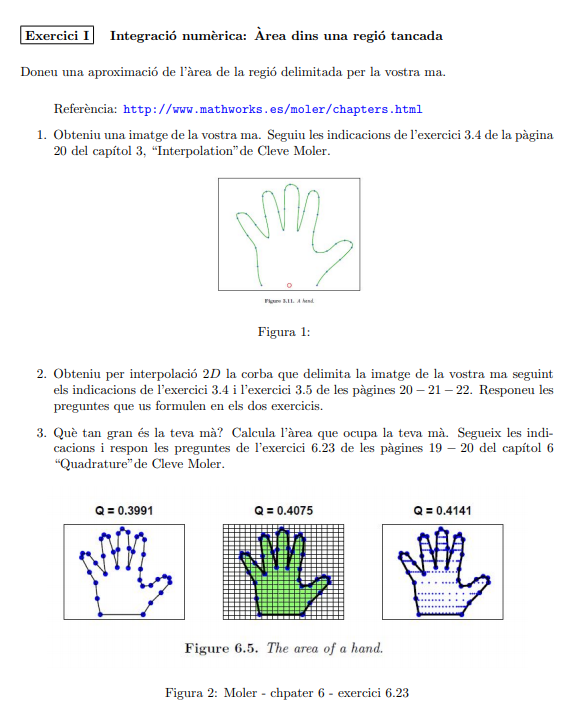

**Exercici 1.2**

clear
format long G
figure('position',get(0,'screensize'))
axes('position',[0 0 1 1])
%[x,y] = ginput;
load myhand.mat

# Splinetx

n = length(x);
s = (1:n)';
t = (1:.05:n)';
u = splinetx(s,x,t);
v = splinetx(s,y,t);
clf reset
plot(x,y,'.',u,v,'-');

# pchiptx

n = length(x);
s = (1:n)';
t = (1:.05:n)';
u = pchiptx(s,x,t);
v = pchiptx(s,y,t);
clf reset
plot(x,y,'.',u,v,'-');

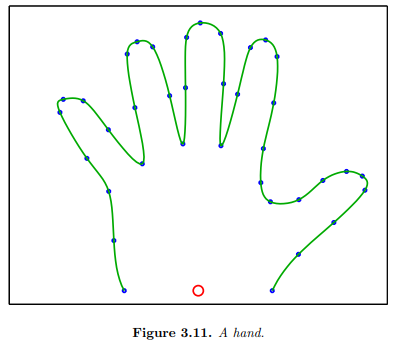

Mas o menos los plots de las manos son parecidas. Aun así prefiero la interpolacion con splinetx ya que hace mejor la forma curvada de la punta de los dedos. Creo que la figura 3.11 se ha hecho con splinetx.

x0 = ((x(end)-x(1))/2)+x(1);
y0 = ((y(end)-y(1))/2)+y(1);
hold on
scatter(x0,y0,1000, 'red');
hold off
x2 = x -x0;
y2 = y - y0;
theta = atan2(y2,x2);
r = sqrt(x2.^2 + y2.^2);
plot(theta,r);

delta = .05;
t = (theta(1):delta:theta(end))';
p = pchiptx(theta,r,t);
s = splinetx(theta,r,t);

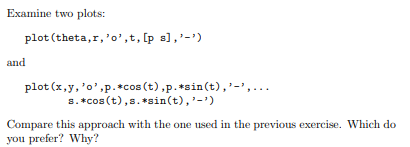

plot(theta,r,'o',t,[p s],'-')
plot(x2,y2,'o',p.*cos(t),p.*sin(t),'-',...
s.*cos(t),s.*sin(t),'-')

**Exercici 1.2**

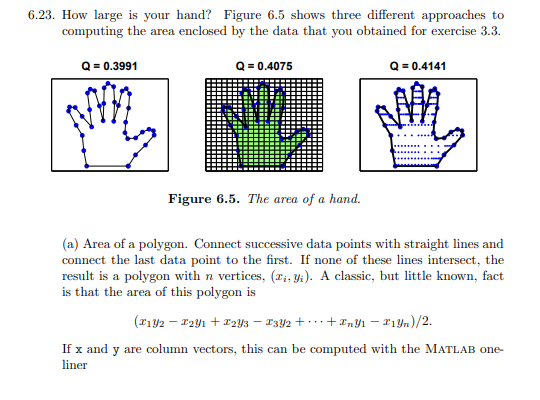

area = (x'*y([2:n 1]) - x([2:n 1])'*y)/2

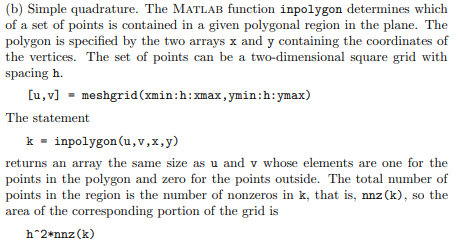

h = 0.005;
xmin = min(x);
xmax = max(x);
ymin = min(y);
ymax = max(y);
[u, v] = meshgrid(xmin:h:xmax,ymin:h:ymax);
k = inpolygon(u,v,x,y);
plot(u,v);
nnz(k);
radi = (h^2)*nnz(k)

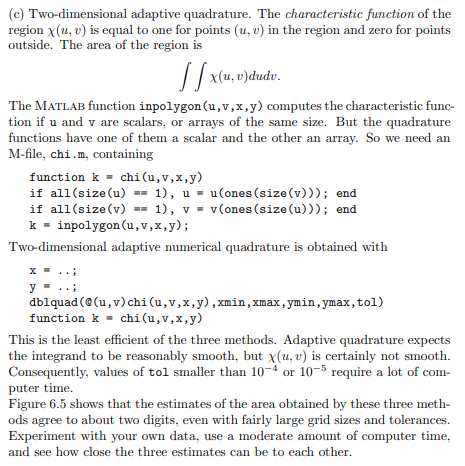

tol = 10^(-4);
radi = dblquad(@(u,v)chi(u,v,x,y),xmin,xmax,ymin,ymax,tol)

# Exercici 2

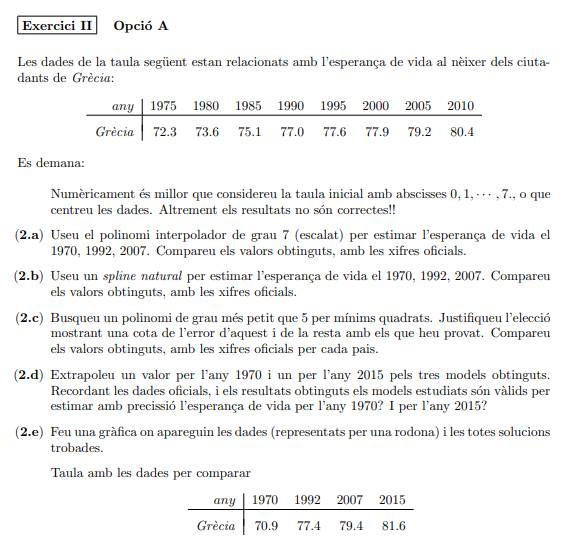

**2.a**

clear
x = [1975 1980 1985 1990 1995 2000 2005 2010];
y = [72.3 73.6 75.1 77.0 77.6 77.9 79.2 80.4];
anys = [1970 1992 2007 2015];
valor_exacto = [70.9 77.4 49.4 81.6];

# Polinomi interpolador grau 7

grau = 7;
[p, ~, mu] = polyfit(x,y,grau);
aproximado = polyval(p,anys,[], mu);
error = error_absoluto(valor_exacto,aproximado);
t = array2table(p, 'RowNames', {'coeficient polinomi'})
t1 = array2table([valor_exacto;aproximado; error], 'VariableNames', {'1970' ,'1992' ,'2007' ,'2010'}, 'RowNames', {'valor', 'aproximat' 'desviat'})

**2.b**

# Spline

x = (x-1975)/(35/7);
anys2 = (anys-1975)/(35/7);
aproximado = interp1(x,y,anys2,'spline');
error = error_absoluto(valor_exacto,aproximado);
t2 = array2table([valor_exacto;aproximado; error], 'VariableNames', {'1970' ,'1992' ,'2007' ,'2010'}, 'RowNames', {'valor', 'aproximat' 'desviat'})

**2.c**

# Polinomio minimos cuadrados

n = 5;
error = zeros(n,length(anys2)+1);
RowNames = {};
for i = 1:n
    coeficientes = polinomio_interpolador_minimos_cuadrados(x, y, i);
    aproximado = polyval(coeficientes,anys2);
    RowNames{i} = strcat('grau ', int2str(i));
    e = error_absoluto(valor_exacto, aproximado);
    error(i,:) = [e, sum(e,2)];
end
t3 = array2table(error,'VariableNames', {'1970' ,'1992' ,'2007' ,'2010', 'Desviacio'}, 'RowNames',RowNames)

**2.d**

**2.e**

# Dades

x = [1975 1980 1985 1990 1995 2000 2005 2010];
y = [72.3 73.6 75.1 77.0 77.6 77.9 79.2 80.4];
scatter(x,y, 'DisplayName','Dades 1');
anys = [1970 1992 2007 2015];
valor_exacto = [70.9 77.4 49.4 81.6];
hold on;
scatter(anys, valor_exacto, 'DisplayName','Dades 2');

# Polinomi interpolador grau 7(PLOT)

grau = 7;
[coeficientes, ~, mu] = polyfit(x,y,grau);
xplot = 1970:2015;
yplot = polyval(coeficientes,xplot,[], mu);
hold on;
plot(xplot,yplot, 'DisplayName','polinomi grau 7');

# Spline(PLOT)

x = (x-1975)/(35/7);
xplot_centrado = ((1970:2015)-1975)/(35/7);
yplot = interp1(x,y,xplot_centrado,'spline');
xplot = 1970:2015;
hold on;
plot(xplot,yplot, 'DisplayName','spline');

# Polinomio minimos cuadrados(Plot)

grado = 2;
[coeficientes] = polinomio_interpolador_minimos_cuadrados(x, y, grado);
xplot_centrado = ((1970:2015)-1975)/(35/7);
yplot = polyval(coeficientes,xplot_centrado);
xplot = 1970:2015;
hold on;
plot(xplot,yplot, 'DisplayName','polinomio minimos cuadrados');
legend

# Exercici 3

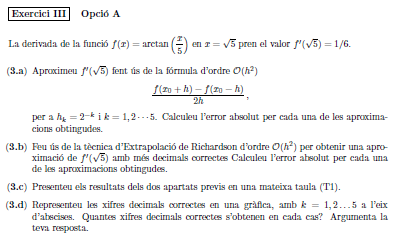

**3.a**

# Error Central difference approximation

clear
syms f(x) x
f(x) = atan(x/5);
point = sqrt(5);
iterations = 5;
base = 2^-1;
df = diff(f,x);
dfx = double(df(point));
N = 1;
[resultat, T] = extrapolation_richardson(f,point,base,iterations, N)

**3.b**

N = 5;
[resultat, T] = extrapolation_richardson(f,point,base,iterations, N);

**3.d**

iterations = 5;
base = 2^-1;
point = sqrt(5);
N_total = 5;
w = 1;
for N = 1:N_total
    [T, resultat] = extrapolation_richardson(f,point,base,iterations, N);
    VariableNames = {'base^k'};
    for i = 1:N
        VariableNames{i+1} = strcat('N ', int2str(i));
    end
    VariableNames{end+1} = 'error';
    t = array2table(T,'VariableNames',VariableNames)
    xplot = w:N_total;
    yplot = floor(abs(log10(T(w:end, end)))-1);
    plot(xplot,yplot);
    if(N == 1)
        hold on;
    end
    w = w + 1;
end
hold off

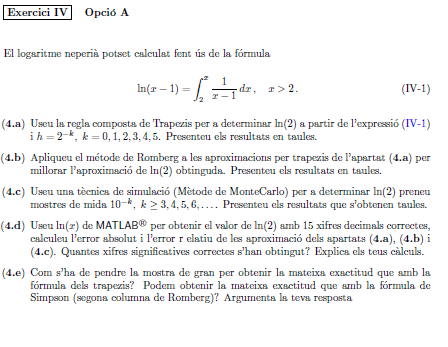

**4.a**

%f = @(x) 1./(x-1);
f = @(x) 4*log(x)

f = function_handle with value:
    @(x)4*log(x)


base = 1/2;
iterations = 6;
a = 2;
b = 3;
[T, ~] = regla_composta_trapezis_iterations(f, a, b, base, iterations)

T =                          0                         1          3.58351893845611        0.0546510810816434
                         1                       0.5          3.62434093297637        0.0138290865613881
                         2                      0.25          3.63470159438299       0.00346842515476187
                         3                     0.125          3.63730220226944      0.000867817268315196
                         4                    0.0625          3.63795302055716      0.000216998980593797
                         5                   0.03125          3.63811576699754      5.42525402122962e-05


**4.b**

N = 4;
[T , ~] = metode_romberg(f,a,b,base, iterations, N)

T =                          0                       0.5          3.58351893845611                         0                         0                         0                         0
                         1                      0.25          3.62434093297637          3.63794826448312                         0                         0                         0
                         2                     0.125          3.63470159438299           3.6381551481852          3.63816894043201                         0                         0
                         3                    0.0625          3.63730220226944          3.63816907156492          3.63816999979024          3.63817001660545      2.93230772996367e-09
                         4                   0.03125          3.63795302055716           3.6381699599864           3.6381700192145          3.63817001952282      1.49333878596281e-11
                         5                  0.015625          3.63811576699754   

**4.c**

b = 5

b =      5


resultat =      3


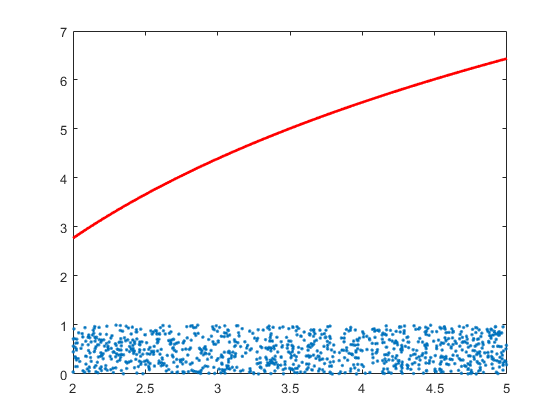

resultat =      3


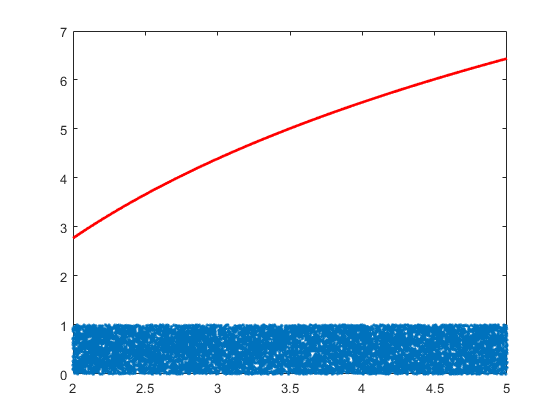

resultat =      3


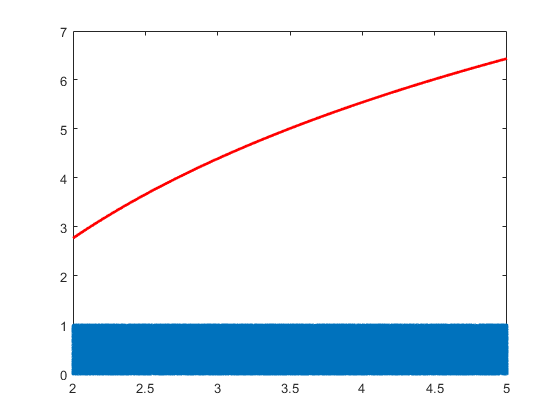

resultat =      3


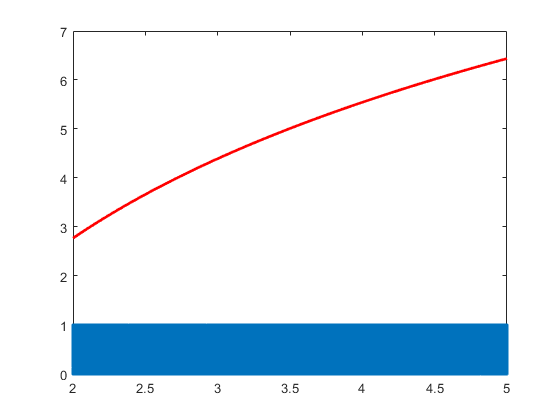

resultat =      3


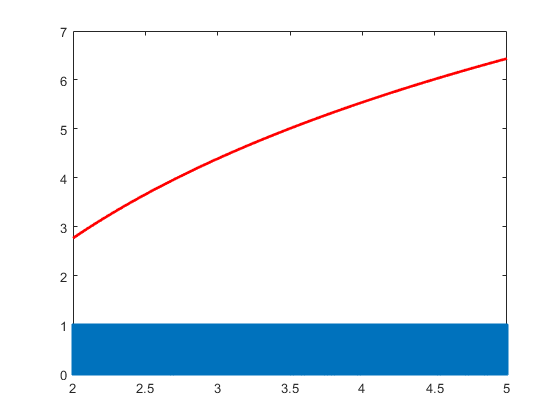

for k = 3:7
    M = 10^k;
    [resultat, points] = metode_montecarlo(f,a,b, M);
    resultat
    t = a:0.05:b; yt = f(t);
    figure
    plot(points(:,1),points(:,2),'.',t,yt,'r','LineWidth',2)
end

function [T, trapezis] = regla_composta_trapezis_iterations(f, a, b, base, iterations)
    k = 0:(iterations-1);
    h = base.^k;
    trapezis = zeros(iterations,1);
    for i = 1:iterations
        sumatorio = f(a:h(i):b);
        sumatorio = sum(sumatorio(2:end-1));
        trapezis(i,1) = h(i)*(((f(a)+f(b))/2) + sumatorio);
    end
    integrate = integral(f,a,b);
    errAbs = abs(trapezis-integrate);
    T = [k' h' trapezis errAbs];
end
function [T, taula_romberg] = metode_romberg(f,a,b,base, iterations, N)
    [~, trapezis] = regla_composta_trapezis_iterations(f,a,b,base, iterations);
    taula_romberg = zeros(iterations,N);
    taula_romberg(:,1) = trapezis;
    for j = 2:N
        for i = j:iterations
            p = 4^(j-1);
            taula_romberg(i,j) = (p*taula_romberg(i,j-1)-taula_romberg(i-1,j-1))/(p-1);
        end
    end
    i = 1:iterations;
    h = base.^i;
    integrate = integral(f,a,b);
    error = abs(taula_romberg(:,N)-integrate);
    error(1:N-1,:) = 0;
    k = 0:(iterations-1);
    T = [k' h' taula_romberg error];
end
function [montecarlo, points] = metode_montecarlo(f,a,b, M)
        k=0;
        points = zeros(M,2);
        maximumfunction = fzero(diff())
        
        for n=1:M
            x = a+rand*(a-b);
            y = rand;
            if y <= f(x) 
                k = k+1;
                points(k,:) = [x,y];
            end
        end
        points = points(1:k,:);
        montecarlo = (b-a)*(k/M);
end
function [T, taula_richardson] = extrapolation_richardson(f,point,base,iterations, N)
    i = 1:iterations;
    h = base.^i;
    taula_richardson = zeros(iterations,N);
     for k = 1:iterations
        taula_richardson(k,1) = double((f(point + (h(k)/2)) - f(point - (h(k)/2)))/h(k));
     end
     for j = 2:N
         for i = j:iterations
             p = 4^(j-1);
             taula_richardson(i,j) = taula_richardson(i,j-1)+((taula_richardson(i,j-1)-taula_richardson(i-1,j-1))/(p-1));
         end
     end
    syms x
    df = diff(f,x);
    dfx = double(df(point));
    error = abs(dfx-taula_richardson(:,N));
    error(1:N-1,:) = 0;
    T = [h' taula_richardson error];
end


function [coeficientes] = polinomio_interpolador_minimos_cuadrados(x, y, grado)
    A = ones(length(x),grado+1);
    i = grado;
    while(i  > 0)
        A(:,((grado+1)-i)) = (x').^i;
        i = i-1;
    end
    b = y';
    coeficientes  = minimos_cuadrados(A,b)';
end
function [x] = minimos_cuadrados(A,b)
    %A'*Ax=A'b
    C = A'*A;
    d = A'*b;
    x = C\d;
end
function [error_absoluto] = error_absoluto(valor_exacto, valor_aproximado)
    error_absoluto = abs(valor_exacto-valor_aproximado);
end